sinewave 1Hz

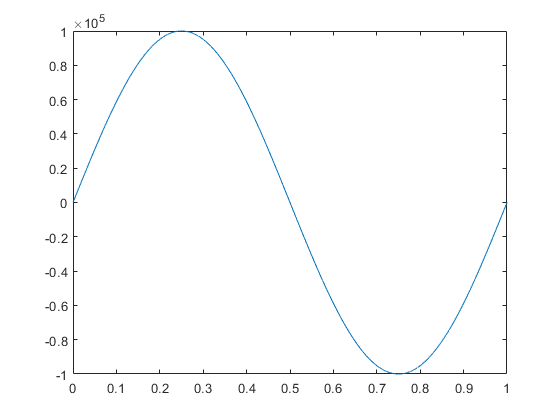

Fs=10e3;        %sample frequency
t=0:1/Fs:1;     %period
fsig1=1;         %signal frequency
sine1=100000*sin(2*pi*fsig1*t);
filename='sine1Hz.txt';
csvwrite(filename,fix(sine1)');
%%delete("sine1Hz");
plot(t,sine1)

sinewave 50 Hz

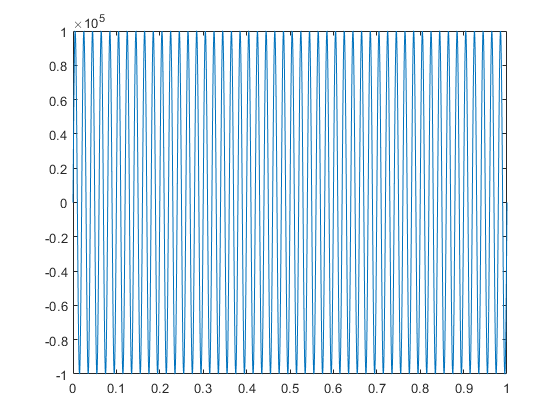

fsig50=50;         %signal frequency
sine50=100000*sin(2*pi*fsig50*t);
filename='sine50Hz.txt';
csvwrite(filename,fix(sine50)');
%%delete("sine1Hz");
plot(t,sine50)

read file content from text file(vector)

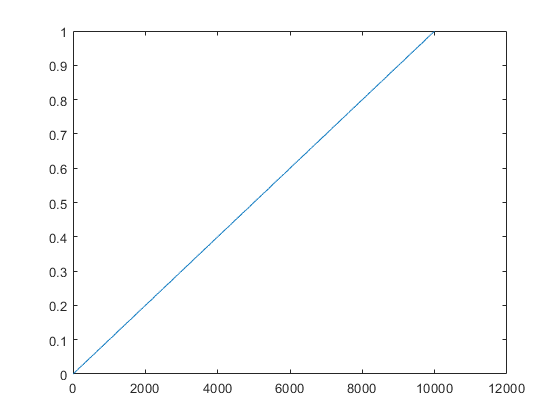

fileID = fopen('sine1Hz.txt','w');
fprintf(fileID,'%6.4f\n',t);
sine5=fscanf(fileID, '%6.4f');

%%fclose(fileID);
%%type sine5Hz.txt;
plot(t, sine5)